# Ex 04: 热导测量

## 动态法测铜

clc, clear, close all
data = transpose(readmatrix("D:\a_RemoteRepo\GH.UCAS-BasicPhysicsExperiment\04-热导测量\data\DY 20241210 电脑数据导出\铜可视 2.rdc", 'FileType', 'text'));
% 第一行是时间, 第二行是分割线（无用）
stc = MyPlot(data(1, :), data(3:end, :));
stc.leg.Visible = 'off';
stc.label.x.String = 'Time (s)';
stc.label.y.String = 'Ouput Voltage (mV)';
ylim([400 1200])
%MyExport_pdf_docked

% 读取峰值时间
data = data(:, data(1, :)> 2600);
for i = 1:12
    [Max(1, i), index] = max(data(2+i, :));
    Max(2, i) = data(1, index);
    %disp(['num ', num2str(i), ': max = ', num2str()])
end
Max
stc = MyPlot(data(1, :), data(3:end, :));

a = Max(2, 8);
Max(2, 8) = Max(2, 9);
Max(2, 9) = a;

[stc, fit] = MyFit_linear(Max(2, :), (0:2:22)*0.01);
stc.label.x.String = 'Time (s)';
stc.label.y.String = 'Reletive Peak Position (cm)';

rho = 8.92e3;
C = 0.385e3;
T = 180;
v = fit.p1
k = rho*C*T*v^2/(4*pi)

MyPrint_xlsx(Max, 1)

## 动态法测铝

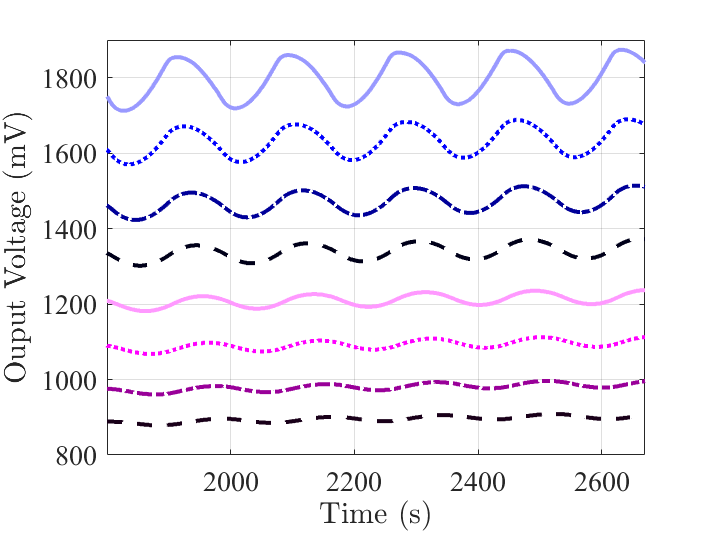

clc, clear, close all
data = transpose(readmatrix("D:\a_RemoteRepo\GH.UCAS-BasicPhysicsExperiment\04-热导测量\data\DY 20241210 电脑数据导出\铝 可视区.rda", 'FileType', 'text'));
data = data(1:10, :);
% 第一行是时间, 第二行是分割线（无用）
stc = MyPlot(data(1, :), data(3:10, :));
stc.leg.Visible = 'off';
stc.label.x.String = 'Time (s)';
stc.label.y.String = 'Ouput Voltage (mV)';
ylim([800 1900])

%MyExport_pdf_docked

% 读取峰值时间
data = data(:, data(1, :)> 2400 & data(1, :) > 2600);
for i = 1:8
    [Max(1, i), index] = max(data(2+i, :));
    Max(2, i) = data(1, index);
    %disp(['num ', num2str(i), ': max = ', num2str()])
end
Max

Max = 1.0e+03 *

    1.8738    1.6895    1.5137    1.3733    1.2366    1.1121    0.9961    0.9058
    2.6275    2.6370    2.6470    2.6600    2.6615    2.6630    2.6685    2.6670


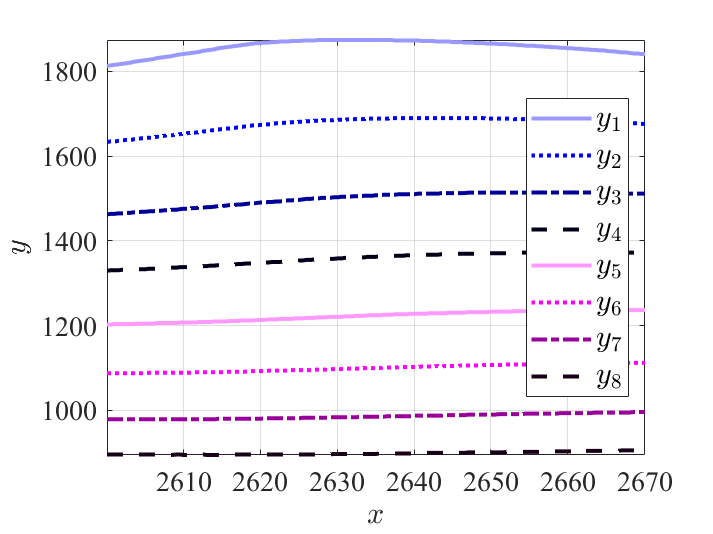

stc = MyPlot(data(1, :), data(3:end, :));



a = Max(2, 7);
Max(2, 7) = Max(2, 8);
Max(2, 8) = a;

[stc, fit] = MyFit_linear(Max(2, :), (0:2:14)*0.01);

y = ax + b
a = 3.0541e-03
b = -8.0354e+00
R^2  = 0.8843707
SSE  = 1.94257e-03
RMSE = 1.79934e-02


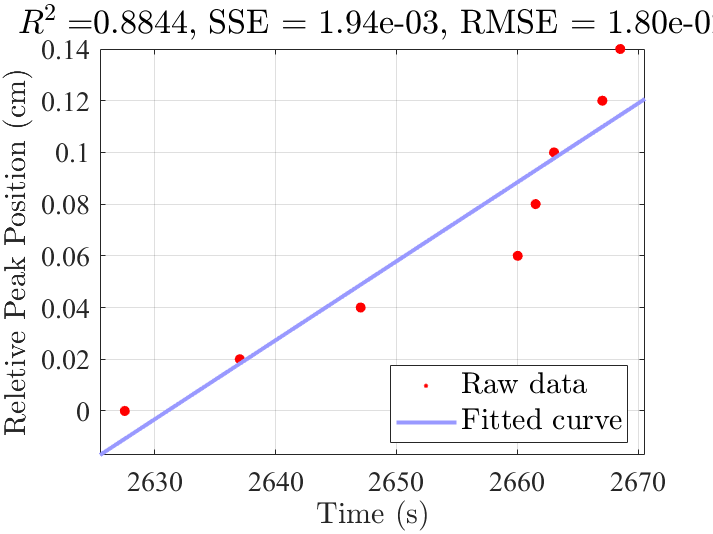

stc.label.x.String = 'Time (s)';
stc.label.y.String = 'Reletive Peak Position (cm)';


rho = 2.7e3;
C = 0.880e3;
T = 180;
v = fit.p1

v = 0.0031

k = rho*C*T*v^2/(4*pi)

k = 317.4435


MyPrint_xlsx(Max, 1)

ans = 2×8 cell 数组
    {'1873.8'}    {'1689.5'}    {'1513.7'}    {'1373.3'}    {'1236.6'}    {'1112.1'}    {'996.1' }    {'905.8' }
    {'2627.5'}    {'2637.0'}    {'2647.0'}    {'2660.0'}    {'2661.5'}    {'2663.0'}    {'2667.0'}    {'2668.5'}


## 温差电动势

t = [27.1  30.3  35.5  40.0  44.9  49.9];
U = [0.880  0.936  0.916  1.068  1.148  1.202];

t = [27.1  30.3    40.0  44.9  49.9];
U = [0.880  0.936    1.068  1.148  1.202];
[stc, fit] = MyFit_linear(t, U);

y = ax + b
a = 1.4200e-02
b = 5.0097e-01
R^2  = 0.9972819
SSE  = 2.03521e-04
RMSE = 8.23653e-03


t_0  = fit.p2/(-fit.p1)

t_0 = -35.2805

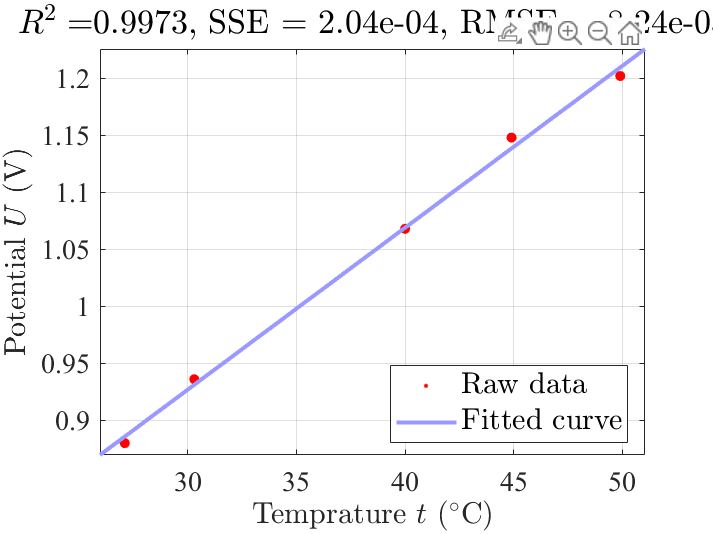

stc.label.x.String = 'Temprature $t\ (^\circ\mathrm{C})$';
stc.label.y.String = 'Potential $U \ (\mathrm{V})$';

## 铜电阻

t = [30.3 35.0 40.0 45.1 50.0];
R = [57.8 58.8 59.9 61.1 62.2];
[stc, fit] = MyFit_linear(t, R);

y = ax + b
a = 2.2429e-01
b = 5.0971e+01
R^2  = 0.9996964
SSE  = 3.74353e-03
RMSE = 3.53248e-02


R_x0 = fit.p2

R_x0 = 50.9705

alpha = fit.p1/fit.p2

alpha = 0.0044

vpa(alpha)

$$ans = 0.0044003637749335028014896487036367$$

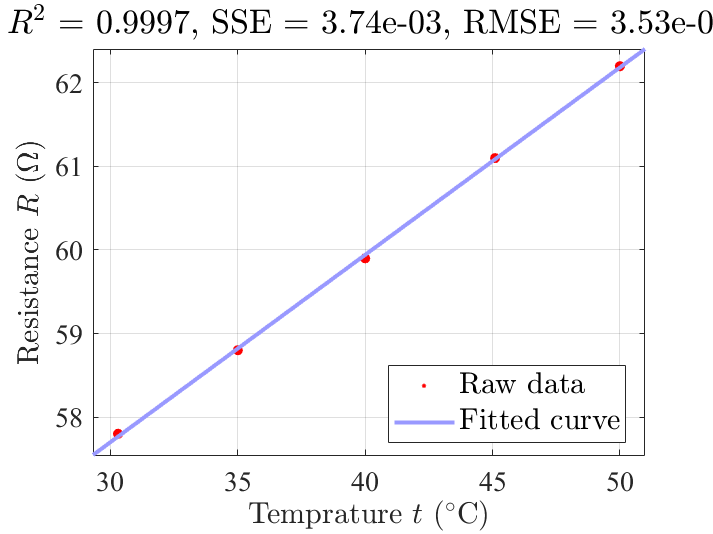

stc.label.x.String = 'Temprature $t\ (^\circ\mathrm{C})$';
stc.label.y.String = 'Resistance $R \ (\Omega)$';

## 热敏电阻

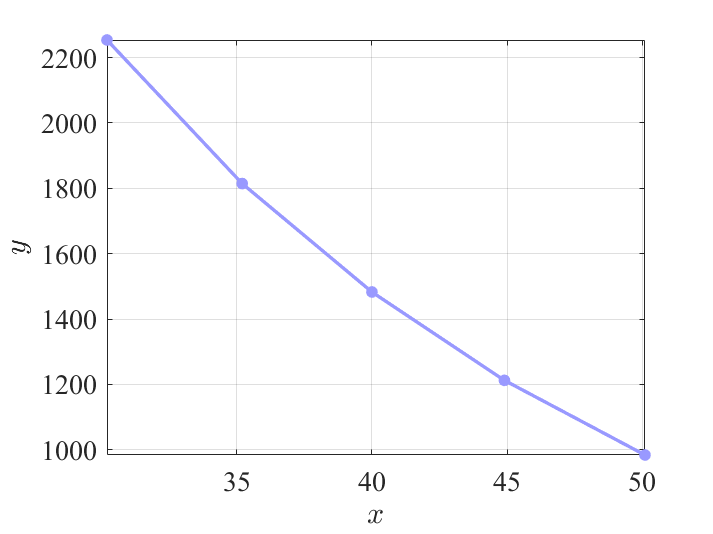

t = [30.2 35.2 40.0 44.9 50.1];
R = [2253.7 1814.4 1482.7 1212.4 984.0];
stc = MyPlot(t, R);


y = log(R);
x = 1./(t + 273.15);
[stc, fit] = MyFit_linear(x, y);

y = ax + b
a = 4.0819e+03
b = -5.7346e+00
R^2  = 0.9999866
SSE  = 5.71007e-06
RMSE = 1.37962e-03


R_x0 = fit.p2

R_x0 = -5.7346

alpha = fit.p1/fit.p2

alpha = -711.7987

vpa(alpha)

$$ans = -711.79873678030742212285986170173$$

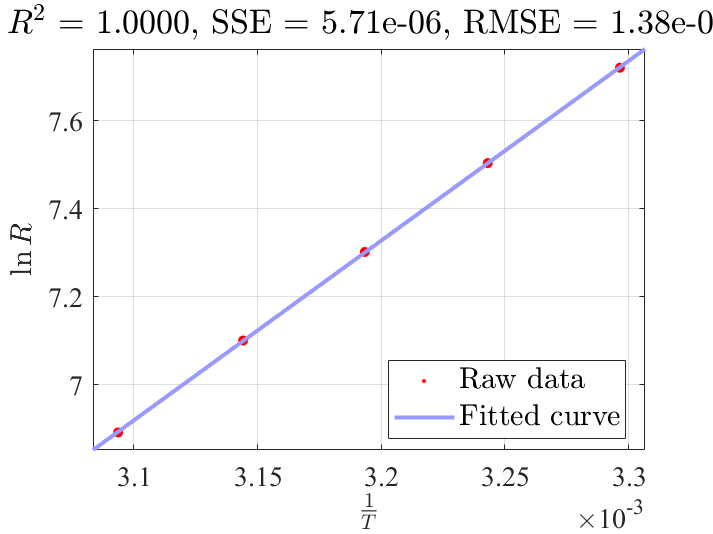

stc.label.x.String = '$\frac{1}{T}$';
stc.label.y.String = '$\ln R$';

%MyExport_pdf

A = exp(fit.p2)

A = 0.0032

B = fit.p1

B = 4.0819e+03


f = @(t) A*exp(B./(t + 273.15))'

f = 包含以下值的 function_handle :
    @(t)A*exp(B./(t+273.15))'


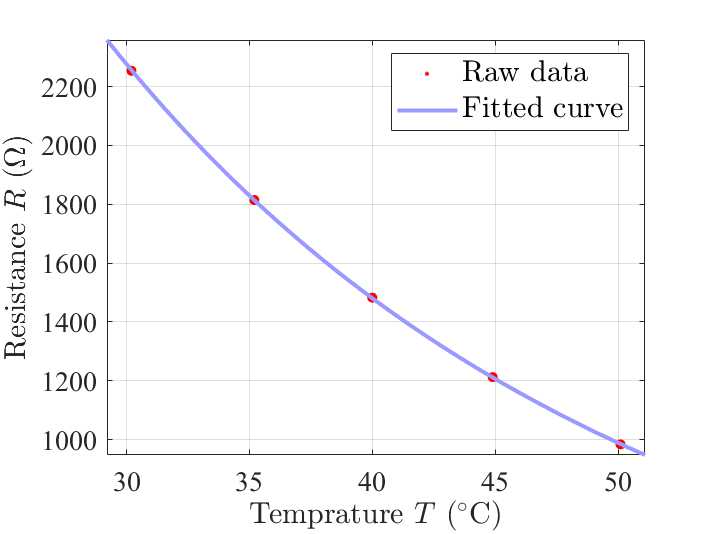

stc = MyPlot_FitAndRaw(f, t, R);
stc.label.x.String = 'Temprature $T\ (^\circ\mathrm{C})$';
stc.label.y.String = 'Resistance $R \ (\Omega)$';


%MyExport_pdf

%t = [40 42.6 45 47.5 48.5  50.1 52.5];
%U = [0 -0.66 -1.24 -1.90 -2.57]*10^(-3)-0.4;
U = [-400 -427 -452 -477 -501]*10^(-3)

U =    -0.4000   -0.4270   -0.4520   -0.4770   -0.5010


t_1 = 40;
lambda = -0.4; m = -10e-3;
t = t_1 + (U - lambda)/m

t =    40.0000   42.7000   45.2000   47.7000   50.1000
